# Walking Arm Trebuchet Dynamic Simulation - ME 326 Ex. 4

**Original Author:** Charlie Refvem

**Author: **Nash Elder

**Last Modified:** 06/05/2020

**Academic Honesty Statement:**

As  a  student  of  Cal  Poly  University,  I, Nash Elder,  pledge  that  I  have  notknowingly  given  nor  received  any  inappropriate  assistance  regarding  exercise 4 in accordance with the course syllabus.

**Description**:

The motion of the walking arm trebuchet as well as the projectile will be modeled and analyzed. The motion is analyzed in 4 regimes: falling, impact, swinging, and flying. Kinematics and vector loops are utilized, as well as kinetic analysis of Newton's 2nd Law and impulse-momentum. This results in a full simulation of the trebuchet and projectile.

**Required Files:**

`    main.mlx            `-    Main script for entire project. Only run this file directly.

`    reg_1_model.slx     `-    Block diagram for simulating Regime 1. Contains two matlab function     

                                                         blocks, `reg_1_EOM` and `reg_1_output` which handle the equations of 

                                                         motion and output equations respectively.

`    jbi2jai.mlx         `-    Live function for handling Regime 2. Relates the system state just before 

                             impact to the system state just after impact.

`    reg_3_model.slx     `-    Block diagram for simulating Regime 3. Contains two matlab function 

                             blocks, `reg_3_EOM` and `reg_3_output` which handle the equations of 

                             motion and output equations respectively.

`    reg_4_model.slx     `-    Block diagram for simulating Regime 4. Contains two matlab function 

                             blocks, `reg_4_EOM` and `reg_4_output` which handle the equations of 

                             motion and output equations respectively.

## Prepare Workspace

This section makes sets up the MATLAB workspace to help everything run smoothly. First, all the figure windows are closed before the script starts.

close all;

## System Constants

This section defines all the constant parameters and settings that will be used across all regimes. First, an empty struct, `P`,  is created to hold all of the constant parameters. This struct will be passed to all functions and Simulink models to guarantee that the parameters match between different parts of the simulation. Doing so guarantees that each constant is only defined one time as part of the struct.

P = struct();

All of the link lengths are defined in units of feet.

P.r_AC = 20/12;
P.r_CD = 20/12;
P.r_BC = 15/12;
P.r_DE = 18/12;
P.r_AF = P.r_AC/2;
P.r_CF = P.r_AC-P.r_AF;
P.r_BD = P.r_BC+P.r_CD;

Gravitational acceleration is in ft/s/s.

P.g = 32.17;

The linear weight density of a 2x2 in lbf/ft is used to find the weight of each link.

P.rho = 0.7;

Masses of each link are calculated in slugs. The mass of link 1 is calculated by assuming uniform density of a 2x2 over the full length between point A and point C.

P.m_1 = P.rho*P.r_AC/P.g;

Link 2 includes the mass of the 20 lbf counterweight in addition to the mass of the 2x2 going from point B to point D.

P.m_w = 20/P.g;
P.m_BD = P.rho*P.r_BD/P.g;
P.m_2 = P.m_w+P.m_BD;

Link 3 includes only the mass of the projectile because the string is of negligable mass.

P.m_3 = 0.25/P.g; % mass of projectile

With the masses defined, the location of point G, the center of mass for link 2, is determined. From this location, remaining dependant link lengths can be resolved.

P.r_DG = (P.r_BD*P.m_w + P.r_CD*P.m_BD)/(P.m_2);
P.r_CG = P.r_DG-P.r_CD;
P.r_BG = P.r_BD-P.r_DG;

The moments of inertia for link 1 and link 2 are calculated in slug*ft^2. Link 3 has no moment of inertia because the string is considered massless.

P.I_1 = 1/12*P.m_1*P.r_AC^2;

Link 2 is a composite body so the moment of inertia must be considered for both parts of the body.

P.I_2 = 1/12*P.m_BD*P.r_BD^2 ...                    % link BD
           + P.m_BD*(P.r_BD/2 - P.r_BG)^2 ...       % P.A.T. for link BD
           + P.m_w*P.r_BG^2;                        % counterweight

A framerate is selected that will eventually be used to set the framerate for an animation.

P.fps = 30;

A release condition is specified as the maximum angle between Link 2 and Link 3 before the projectile leaves the mechanism.

P.th_release = deg2rad(165);                            

Finally, a struct will be created for each regime to hold the settings and results associated with that regime specifically.

reg1 = struct();
reg3 = struct();
reg4 = struct();

## Regime 1 - Falling

This section will handle everything associated with Regime 1, which covers the falling motion of the trebuchet before it hits the ground. 

Observe the regime 1 Simulink diagram based upon hand calculations and equations of motion:

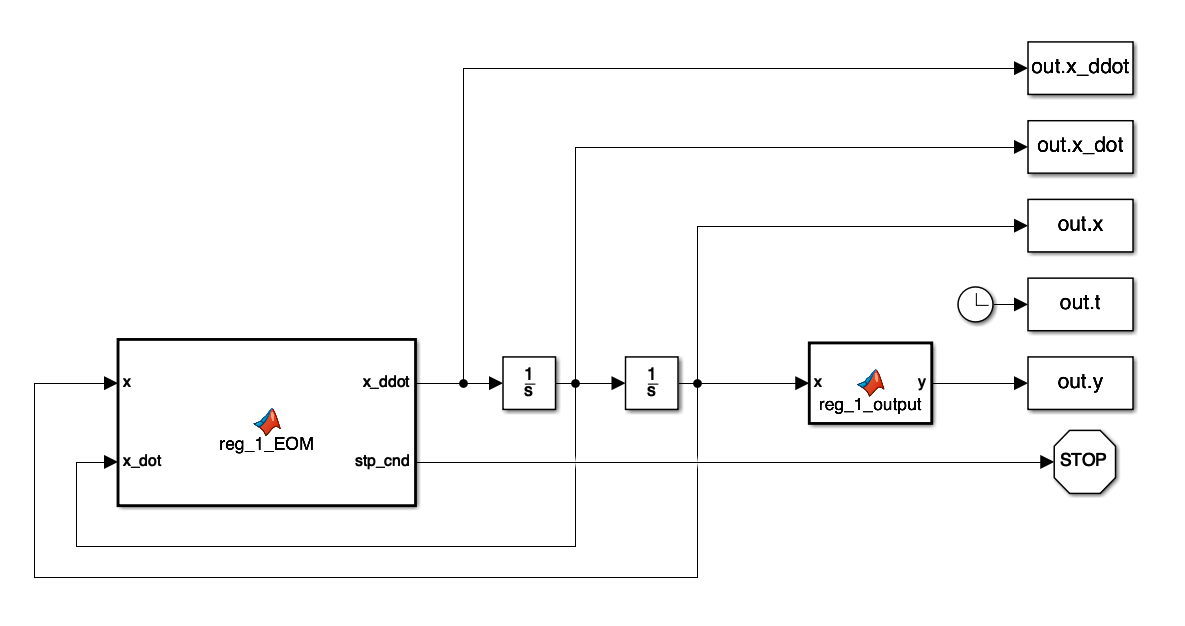

### Initial conditions

All initial angles, in radians, are defined. These angles can be adjusted to improve the performance of the trebuchet and prevent interference with the ground before the projectile flies off.

reg1.xi     = [ deg2rad(-35)     % th1                    <------
                deg2rad(95)      % th2                    <------
                deg2rad(100) ];  % th3                    <------

Similarly, the initial angular velocities are defined, all in radians per second. The system starts at rest, so these velocities are all zero.

reg1.xi_dot = [ 0                % th1_dot
                0                % th2_dot
                0 ];             % th3_dot

### Simulation

The simulation for Regime 1 must run long enough to guarantee that the trebuchet impacts with the ground. This will be accomplished by running the simulation indefinitely and relying on a "Stop Simulation" block in Simulink to end the simulation. Even though the simulation will automatically determine when to end, the simulation does need to know when to start, so a start time is defined for the simulation.

reg1.ti     = 0;

Here the Simulink model is run and the output is stored for post processing.

reg1.out    = sim('reg_1_model');

### Post Processing

This section resamples the output to achieve a constant sample rate with respect to time to use for the animation. A constant sample rate will help the animation to run closer to real-time. First the stop time for regime 1 is calculated and used to find a new set of time samples at a constant interval near the desired framerate.

First, the time of the final simulation step is recorded as the stop time for Regime 1.

reg1.tf     = reg1.out.t(end);
reg1.xf     = reg1.out.x(end,:)';
reg1.xf_dot = reg1.out.x_dot(end,:)';

The simulation of Regime 1 ended automatically when the trebuchet made impact with the ground. Because this end time occurs at an arbitrary point in time, it will not be possible to resample at the desired framrate and end up with an integer number of samples. Instead, the output data will be sampled at whatever framerate is closest to the desired framerate such that an integer number of samples are created.

The stop time and desired framerate are used to determine the number of data points to use in resampling.

reg1.N      = length(reg1.ti:(1/P.fps):reg1.tf);

The number of data points is used to create a new list of sample times with a sample rate very near the desired framerate.

reg1.t      = linspace(reg1.ti,reg1.tf,reg1.N)';

WIth the new list of sample times, the output of Regime 1 can be resampled using linear interpolation.

reg1.pts    = interp1(reg1.out.t,reg1.out.y,reg1.t);

The actual framerate can be determined after the new list of samples is created.

fprintf('Regime 1 has been resampled at a framerate of %2.2f FPS resulting in %2.0f samples.', ...
    1/(reg1.t(2)-reg1.t(1)),reg1.N);

Regime 1 has been resampled at a framerate of 29.62 FPS resulting in 29 samples.

## Regime 2 - Impact

### State Transformation

This section handles the instantaneous change in state between the falling regime and the swinging regime. This is achieved by running a function that analyzes the state of the system just before impact (JBI) to determine the state of the system just after impact (JAI). Regime 2 occurs instantaneously and does not require its own simulation.

[reg3.xi, reg3.xi_dot] = jbi2jai(reg1.xf, reg1.xf_dot, P);

## Regime 3 - Swinging

Observe the regime 3 Simulink diagram based upon hand calculations and equations of motion:

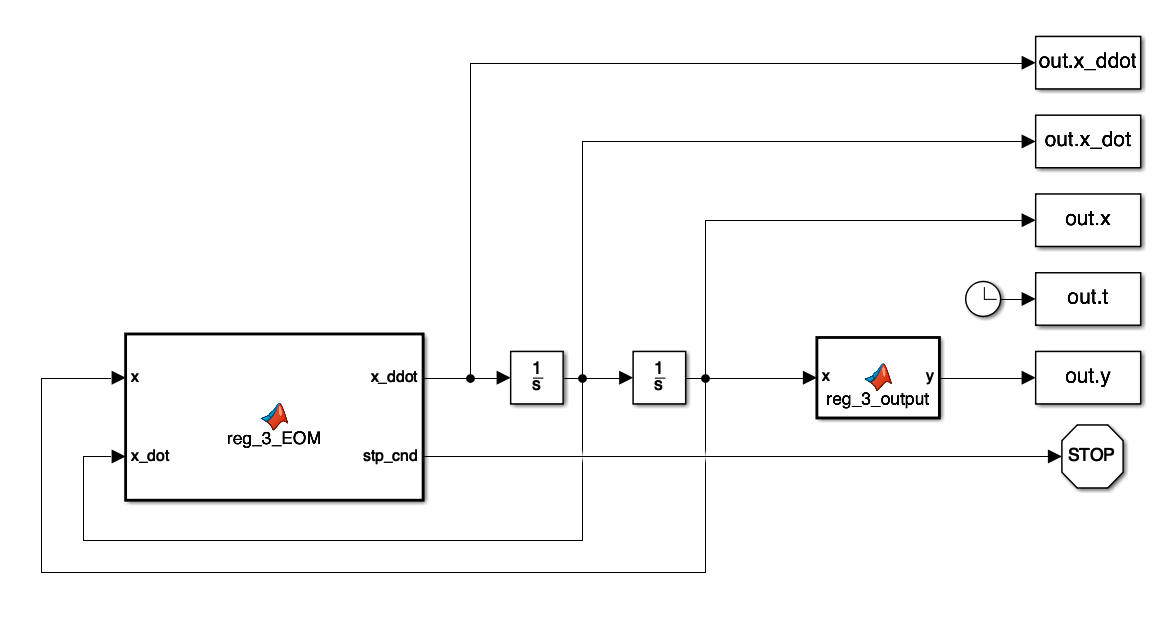

### Initial Conditions

The initial conditions for Regime 3 have already been handled during Regime 2.

### Simulation

In theory, the start time for Regime 3 should be the stop time from Regime 1 if the impact is modeled as an impulse.

reg3.ti = 0;                                            % <------
reg3.out = sim('reg_3_model.slx');

### Post Processing

This section resamples the output to achieve a constant sample rate with respect to time to use for the animation. A constant sample rate will help the animation to run closer to real-time. First the stop time for regime 1 is calculated and used to find a new set of time samples at a constant interval near the desired framerate.

First, the time of the final simulation step is recorded as the stop time for Regime 1.

reg3.tf     = reg3.out.t(end);
reg3.xf     = reg3.out.x(end,:)';
reg3.xf_dot = reg3.out.x_dot(end,:)';

The simulation of Regime 1 ended automatically when the trebuchet made impact with the ground. Because this end time occurs at an arbitrary point in time, it will not be possible to resample at the desired framrate and end up with an integer number of samples. Instead, the output data will be sampled at whatever framerate is closest to the desired framerate such that an integer number of samples are created.

The stop time and desired framerate are used to determine the number of data points to use in resampling.

reg3.N      = length(reg3.ti:(1/P.fps):reg3.tf);

The number of data points is used to create a new list of sample times with a sample rate very near the desired framerate.

reg3.t      = linspace(reg3.ti,reg3.tf,reg3.N)';

WIth the new list of sample times, the output of Regime 1 can be resampled using linear interpolation.

reg3.pts    = interp1(reg3.out.t,reg3.out.y,reg3.t);

Error using interp1>reshapeAndSortXandV (line 424)
X and V must be of the same length.
Error in interp1 (line 93)
    [X,V,orig_size_v] = reshapeAndSortXandV(varargin{1},varargin{2});

The actual framerate can be determined after the new list of samples is created.

fprintf('Regime 3 has been resampled at a framerate of %2.2f FPS resulting in %2.0f samples.', ...
    1/(reg3.t(2)-reg3.t(1)),reg3.N);

## Regime 4 - Flying

Observe the regime 3 Simulink diagram based upon hand calculations and equations of motion:

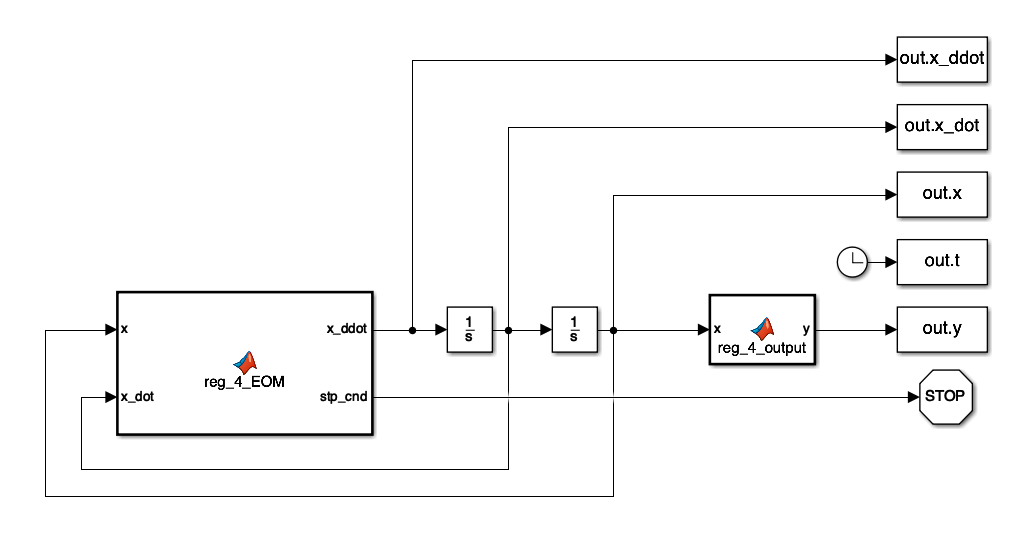

### Initial Conditions

reg4.xi     = [  0                                      % <------
                 0 ];                                   % <------
reg4.xi_dot = [  0                                      % <------
                 0 ];                                   % <------

### Simulation

reg4.ti = 0;                                            % <------
reg4.out = sim('reg_4_model.slx');

### Post Processing

First, the time of the final simulation step is recorded as the stop time for Regime 1.

reg4.tf     = reg4.out.t(end);
reg4.xf     = reg4.out.x(end,:)';
reg4.xf_dot = reg4.out.x_dot(end,:)';

The stop time and desired framerate are used to determine the number of data points to use in resampling.

reg4.N      = length(reg4.ti:(1/P.fps):reg4.tf);

The number of data points is used to create a new list of sample times with a sample rate very near the desired framerate.

reg4.t      = linspace(reg4.ti,reg4.tf,reg4.N)';

WIth the new list of sample times, the output of Regime 4 can be resampled using linear interpolation.

reg4.pts    = interp1(reg4.out.t,reg4.out.y,reg4.t);

The actual framerate can be determined after the new list of samples is created.

fprintf('Regime 4 has been resampled at a framerate of %2.2f FPS resulting in %2.0f samples.', ...
    1/(reg4.t(2)-reg4.t(1)),reg4.N);

## Animation

First, a new figure window is created and configured  to be visible outside of this live script with the desired formatting. The animations for each regime will all show on the same figure.

anim = figure(1);
anim.Visible = 'On';
anim.Position = [600 200 800 600];
anim.Renderer = 'painters';
anim.Color = 'white';

### Regime 1

This section loops through all of the points for Regime 1 while plotting each frame one by one.

for n=1:reg1.N
    
    % Find range of points to plot for trails.
    reg1.ind = reg1.out.t <= reg1.t(n);
    
    % Re-focus on previously defined figure
    figure(anim)
    
    % Plot the "ground"
    fill([-100 100 100 -100],[-100 -100 0 0],[0.5 0.5 0.5]);
    
    hold('on');
    
    % Plot the trail for each point of interest (E and G)
    plot(reg1.out.y(reg1.ind,9), reg1.out.y(reg1.ind,10),':black','linewidth',1);
    plot(reg1.out.y(reg1.ind,13),reg1.out.y(reg1.ind,14),':black','linewidth',2);
    
    % Plot the mechanism outline (D -> B -> C -> A)
    plot(reg1.pts(n,[7 3 5 1]),reg1.pts(n,[8 4 6 2]),'color',[0.75 0.75 0.75],'linewidth',3);
    
    % Plot the dots for each joint of the mechanism (A, B, C, E)
    plot(reg1.pts(n,[1 3 5 7 9]),reg1.pts(n,[2 4 6 8 10]),'o','MarkerFaceColor','black','MarkerSize',3);
    
    % Plot the string (D -> E)
    plot(reg1.pts(n,[7 9]),reg1.pts(n,[8 10]),'color',[0.75 0.75 0.75],'linewidth',1);
    
    % Plot the dot for the counterweight (G)
    plot(reg1.pts(n,13),reg1.pts(n,14),'o','MarkerFaceColor','black','MarkerSize',6);
    
    % Plot the dot for the projectile (E)
    plot(reg1.pts(n,9),reg1.pts(n,10),'o','MarkerFaceColor','yellow','MarkerSize',8);
    
    hold('off');
    
    xlabel('Horizontal Displacement, [ft]');
    ylabel('Vertical Displacement, [ft]');
    
    axis('equal');
    axis([-4 2 -1 5]);
    
    grid('on');
    
    drawnow;
end

### Regime 3

This section loops through all of the points for Regime 3 while plotting each frame one by one.

for n=1:reg3.N
    
    % Find range of points to plot for trails.
    reg3.ind = reg3.out.t <= reg3.t(n);
    
    % Re-focus on previously defined figure
    figure(anim)
    
    % Plot the "ground"
    fill([-100 100 100 -100],[-100 -100 0 0],[0.5 0.5 0.5]);
    
    hold('on');
    
    % Plot the trail for each point of interest (E and G)
    plot(reg3.out.y(reg3.ind,9), reg3.out.y(reg3.ind,10),':black','linewidth',1);
    plot(reg3.out.y(reg3.ind,13),reg3.out.y(reg3.ind,14),':black','linewidth',2);
    
    % Plot the mechanism outline (D -> B -> C -> A)
    plot(reg3.pts(n,[7 3 5 1]),reg3.pts(n,[8 4 6 2]),'color',[0.75 0.75 0.75],'linewidth',3);
    
    % Plot the dots for each joint of the mechanism (A, B, C, E)
    plot(reg3.pts(n,[1 3 5 7 9]),reg3.pts(n,[2 4 6 8 10]),'o','MarkerFaceColor','black','MarkerSize',3);
    
    % Plot the string (D -> E)
    plot(reg3.pts(n,[7 9]),reg3.pts(n,[8 10]),'color',[0.75 0.75 0.75],'linewidth',1);
    
    % Plot the dot for the counterweight (G)
    plot(reg3.pts(n,13),reg3.pts(n,14),'o','MarkerFaceColor','black','MarkerSize',6);
    
    % Plot the dot for the projectile (E)
    plot(reg3.pts(n,9),reg3.pts(n,10),'o','MarkerFaceColor','yellow','MarkerSize',8);
    
    hold('off');
    
    xlabel('Horizontal Displacement, [ft]');
    ylabel('Vertical Displacement, [ft]');
    
    axis('equal');
    axis([-4 2 -1 5]);
    
    grid('on');
    
    drawnow;
end

### Regime 4

This section loops through all of the points for Regime 3 while plotting each frame one by one.

for n=1:reg4.N
    
    % Find range of points to plot for trails.
    reg4.ind = reg4.out.t <= reg4.t(n);
    
    % Re-focus on previously defined figure
    figure(anim)
    
    % Plot the "ground"
    fill([-100 100 100 -100],[-100 -100 0 0],[0.5 0.5 0.5]);
    
    hold('on');
    
    % Plot the trail for each point of interest (E and G)
    plot(reg4.out.y(reg4.ind,9), reg4.out.y(reg4.ind,10),':black','linewidth',1);
    plot(reg4.out.y(reg4.ind,13),reg4.out.y(reg4.ind,14),':black','linewidth',2);
    
    % Plot the mechanism outline (D -> B -> C -> A)
    plot(reg4.pts(n,[7 3 5 1]),reg4.pts(n,[8 4 6 2]),'color',[0.75 0.75 0.75],'linewidth',3);
    
    % Plot the dots for each joint of the mechanism (A, B, C, E)
    plot(reg4.pts(n,[1 3 5 7 9]),reg4.pts(n,[2 4 6 8 10]),'o','MarkerFaceColor','black','MarkerSize',3);
    
    % Plot the string (D -> E)
    plot(reg4.pts(n,[7 9]),reg4.pts(n,[8 10]),'color',[0.75 0.75 0.75],'linewidth',1);
    
    % Plot the dot for the counterweight (G)
    plot(reg4.pts(n,13),reg4.pts(n,14),'o','MarkerFaceColor','black','MarkerSize',6);
    
    % Plot the dot for the projectile (E)
    plot(reg4.pts(n,9),reg4.pts(n,10),'o','MarkerFaceColor','yellow','MarkerSize',8);
    
    hold('off');
    
    xlabel('Horizontal Displacement, [ft]');
    ylabel('Vertical Displacement, [ft]');
    
    axis('equal');
    axis([-4 2 -1 5]);
    
    grid('on');
    
    drawnow;
end      

### Discussion Questions

1. In this assignment you are not required to simulate the motion of the mechanism once the projectile departs. Describe how you could analyze the residual motion of the mechanism by simulating an additional regime of motion. In your description provide details about your proposed method, including, but not limited to, the number and selection of state variables. 						

After the projectile leaves, there is no point mass at E. This means that the link 3 can be ignored. Analysis could be done using links 1 and 2 and finding equations of motion for the links with a pivot point at A. This analysis would utilize the state variable xdot1, ydot1, xddot1, yddot1, xdot2, ydot2, xddot2, yddot2, thetadot1, thetaddot1, thetadot2, thetaddot2, thetadot3, and thetaddot3. As in regimes 1 and 3, kinematic analysis using these state vectors can be done, as well as kinetic analysis using Newton Euler method, FBD = KD. Constraints for this could be when the trebuchet comes to rest when point D touches the ground. Using this, a Simulink model and Matlab code could be created similar to Regime 3. 

2. Determine the theoretical maximum distance that the projectile could travel under ideal conditions, assuming that the ground is flat and level. Compare this theoretical maximum distance to the actual distance that your simulated projectile travels. Why does your simulation throw the projectile a shorter distance than the theoretical maximum? What adjustments or tuning could be performed to maximize the travel distance? 	

I cannot give a value for maximum distance, however the theoretical value would be greater than the actual distance traveled. The trebuchet will not perfectly convert potential energy into kinetic energy, and this is why the projectile will not travel the theoretical maximum distance. Also the theoretical maximum might not be accounting for aerodynamic drag on the projectile in air, which would lead to a shorter distance. Adjusting to a more ideal drop angle, such as they do in the videos on Instructables, would lead to a more optimized system and greater distance. Optimizing the amount of weights put on the end of link 2 would also help with distance.

3. In regards to your simulation results, what percentage of the initial potential energy (of the whole system) is converted to kinetic energy of the projectile at the time of release? In other words, how efficient is the trebuchet at converting potential energy to kinetic energy? Considering your answer to the previous question, does maximum efficiency translate to maximum distance traveled? 						

I cannot give a value for this percentage. Maximum efficiency of the system does not totally translate to maximum distance. The system would still need to be optimized for ideal drop angle, as well as the proper amount of weights added. Maximum efficiency with unideal launch conditions would improve range certainly, however the other conditions must be ideal to reach the maximum distance.